# Sinusoida zmodulowana - sweep, chirp

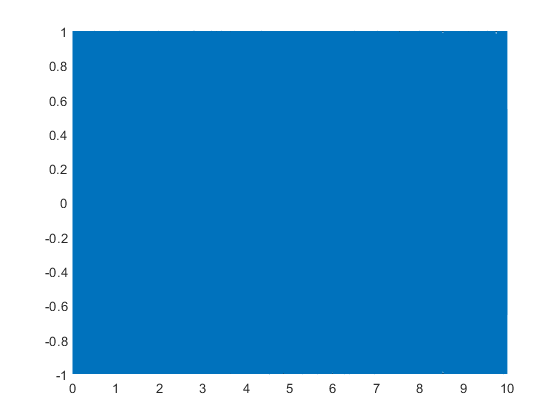

clear all
init.freq = 44100;
init.freq_change = 5000;
init.init_freq = 1000;
init.end_time = 10;

t = 0:1/init.freq:init.end_time;

out = arrayfun(@(x) s(x, init), t);

sound(out, init.freq)

clf
figure(1)
plot(t,out)

funkcja zwracajaca sinusoide:

function y = s(t, i)
    y = sin(2*pi*( t*i.init_freq+(i.freq_change-i.init_freq)/(2*i.end_time)*t^2 ));
    %y = sin(t+i.freq_change*);
end